clc; clear all; close all;

% Define symbolic variables
syms h(t) K h0 A_output A_tank g

% Set up the differential equation
diffeq = diff(h,t) == -K*sqrt(h)

$$diffeq(t) = \frac{\partial }{\partial t}h\left(t\right)=-K\,\sqrt{h\left(t\right)}$$


% Solve the differential equation without initial condition
hSol(t) = dsolve(diffeq)

$$hSol(t) = \left(\begin{array}{c} {\left(C_{1}-\frac{K\,t}{2}\right)}^{2}\\ 0 \end{array}\right)$$


% Solve the differential equation with initial condition
cond = h(0) == h0;
hSol2(t) = dsolve(diffeq, cond);
hSol2(t) = subs(hSol2, K, A_output/A_tank * sqrt(2*g))

$$hSol2(t) = \left(\begin{array}{c} {\left(\sqrt{h_{0}}+\frac{\sqrt{2}\,A_{\mathrm{output}}\,\sqrt{g}\,t}{2\,A_{\mathrm{tank}}}\right)}^{2}\\ {\left(\sqrt{h_{0}}-\frac{\sqrt{2}\,A_{\mathrm{output}}\,\sqrt{g}\,t}{2\,A_{\mathrm{tank}}}\right)}^{2} \end{array}\right)$$


% Substitute symbolic variable with numerical value
hSol2(t) = subs(hSol2, A_output, pi*(0.05/2)^2);
hSol2(t) = subs(hSol2, A_tank, pi*(0.5/2)^2);
hSol2(t) = subs(hSol2, g, 10);
hSol2(t) = subs(hSol2, h0, 1);

% Present solution of differential equation with numerical constants
hSol2;

% Select the correct solution (so that the time will be positive)
h =sym2cell(hSol2(t))

h = 2×1 cell array
    {[((2^(1/2)*10^(1/2)*t)/200 + 1)^2]}
    {[((2^(1/2)*10^(1/2)*t)/200 - 1)^2]}



% Set the height to zero, and solve equation for the time variable
eq = 0 == cell2sym(h(2))

$$eq = 0={\left(\frac{\sqrt{2}\,\sqrt{10}\,t}{200}-1\right)}^{2}$$

t = vpa(solve(eq,t))

$$t = \left(\begin{array}{c} 44.721359549995793928183473374626\\ 44.721359549995793928183473374626 \end{array}\right)$$


% Plotting of the resulting equation (unrealistic)
dt = 10^-4;
t = 0;
i = 1;
wasZero = false;
while(t <= 100)
    height = ((sqrt(2)*sqrt(10)*t)/200 - 1)^2;
    
    h_plot_analytical(i) = height;
    t_plot(i) = t;
    
    t = t + dt;
    i = i + 1;
end

fig = figure;
plot(t_plot,h_plot_analytical, 'r', 'LineWidth', 2)
title("Analytical Tank Problem Unrealistic", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t)", 'Interpreter', 'latex')
ylim([-0.1 1])
grid
filename = "analytical_solution_tank_problem_unrealistic.eps"

filename = "analytical_solution_tank_problem_unrealistic.eps"

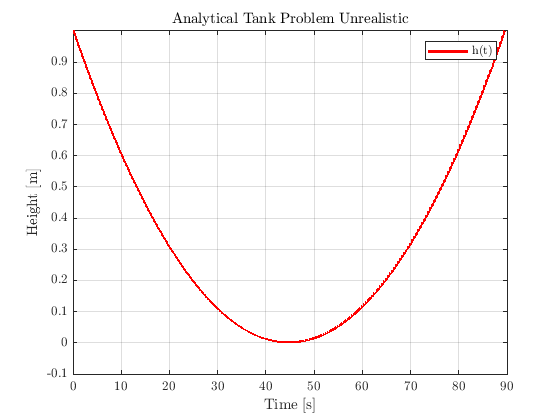

saveas(fig,filename, 'epsc')


% Plotting of the resulting equation (realistic)
dt = 10^-4;
t = 0;
i = 1;
wasZero = false;
while(t <= 100)
    height = ((sqrt(2)*sqrt(10)*t)/200 - 1)^2;
    if(height >= 0.000001)
        h_plot_analytical(i) = height;
    else
        wasZero = true;
        h_plot_analytical(i) = 0;
    end

    if(wasZero)
        h_plot_analytical(i) = 0;
    end
t_plot(i) = t;

t = t + dt;
i = i + 1;
end

fig = figure;
plot(t_plot,h_plot_analytical, 'r', 'LineWidth', 2)
title("Analytical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t)", 'Interpreter', 'latex')
ylim([-0.1 1])
grid
filename = "analytical_solution_tank_problem.eps"

filename = "analytical_solution_tank_problem.eps"

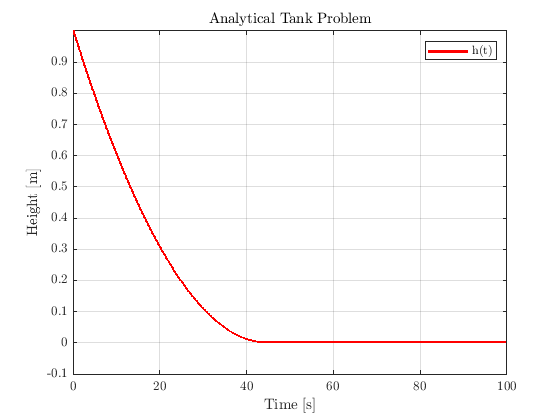

saveas(fig,filename, 'epsc')


[height, idx] = min(h_plot_analytical);
time_at_zero = t_plot(idx(1))

time_at_zero =           44.6767000003596



ddiffeq = diff(diffeq)

$$ddiffeq(t) = \frac{\partial^{2}}{\partial t^{2}}h\left(t\right)=-\frac{K\,\frac{\partial }{\partial t}h\left(t\right)}{2\,\sqrt{h\left(t\right)}}$$

## Numerical approach

simTime = 100; % s
t = 0; % Start time
dt = 10^-4;
idx = 1; % Index for logging

A_output = pi*(0.05/2)^2;
A_tank = pi*(0.5/2)^2;
g = 10;
h = 1;
while t < simTime
    % Calculations
    v = sqrt(2*g*h);
    Q = v*A_output;
    hDot = -Q/A_tank;

    % Save results for plotting
    t_plot_numerical(idx) = t;
    h_plot_numerical(idx) = h;
    h_DotPlot(idx) = hDot;

    % Time integrate and update time, index variables
    h = h+hDot*dt;          % Height
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

fig = figure;
plot(t_plot_numerical,h_plot_numerical, 'k', 'LineWidth', 2)

title("Numerical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t)", 'Interpreter', 'latex')
ylim([-0.1 1])
grid
filename = "numerical_solution_tank_problem.eps"

filename = "numerical_solution_tank_problem.eps"

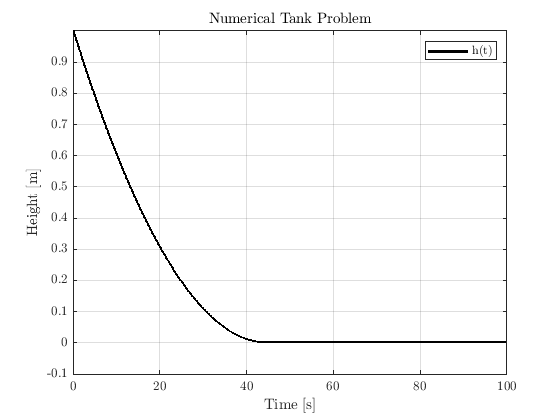

saveas(fig,filename, 'epsc')

hold off

fig = figure;
plot(t_plot_numerical,h_DotPlot, 'b', 'LineWidth', 2)

filename = "numerical_dot_solution_tank_problem.eps"

filename = "numerical_dot_solution_tank_problem.eps"

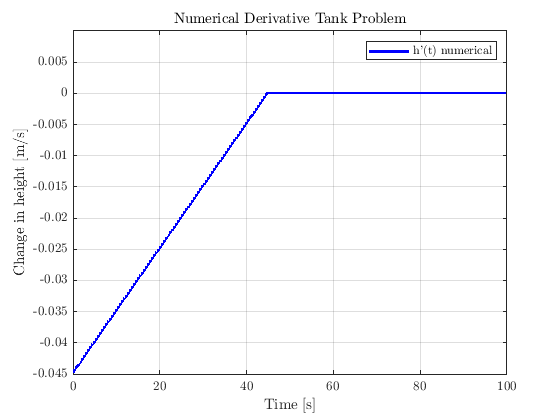

title("Numerical Derivative Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Change in height [m/s]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h'(t) numerical", 'Interpreter', 'latex')
grid on
ylim([-0.045 0.01])
saveas(fig,filename, 'epsc')


fig = figure;
hold off
plot(t_plot_numerical,h_plot_analytical, 'r', 'LineWidth', 2)
hold on
plot(t_plot_numerical,h_plot_numerical, 'ko', 'MarkerIndices', 1:50000:length(h_plot_numerical),'LineWidth',2)

title("Analytical vs. Numerical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t) analytical", "h(t) numerical", 'Interpreter', 'latex')
ylim([-0.1 1])
grid on
filename = "analytical_vs_numerical_solution_tank_problem.eps"

filename = "analytical_vs_numerical_solution_tank_problem.eps"

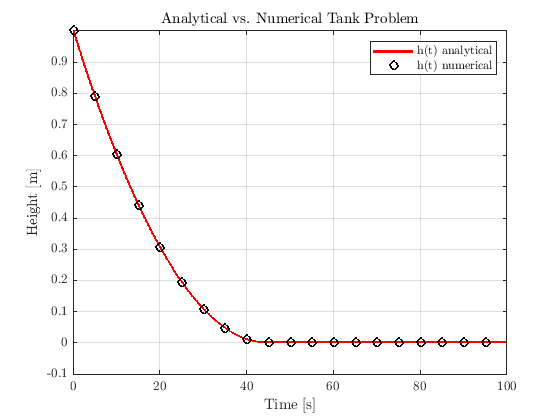

saveas(fig,filename, 'epsc')